Apartado B

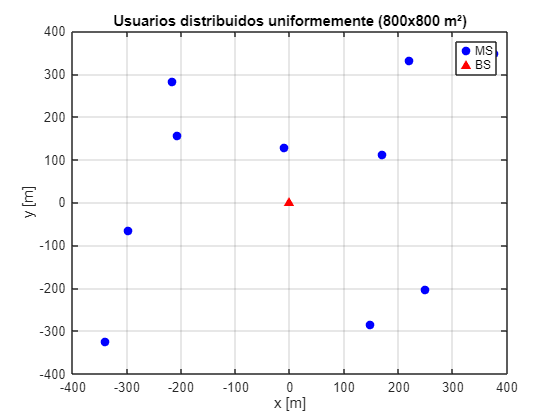

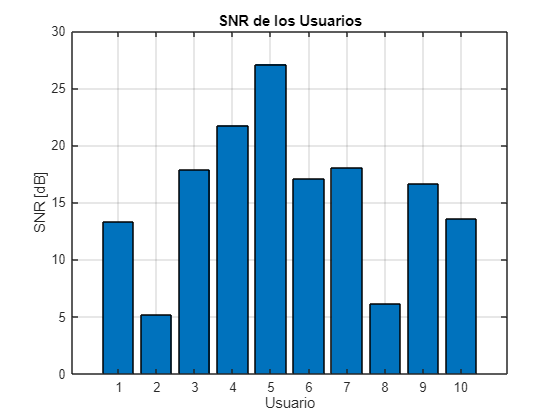

Usuario seleccionado final: 10      Vector de retardo final: 6  45  12  22  29   2  16   3  10   0


Usuario seleccionado final: 10      Vector de retardo final: 48   5  12  21  23  18  16   9  38   0


Usuario seleccionado final: 1      Vector de retardo final: 0  29  28   9  22  33  24  27  54   1


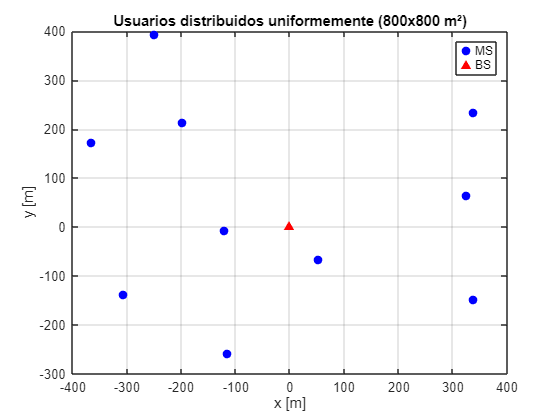

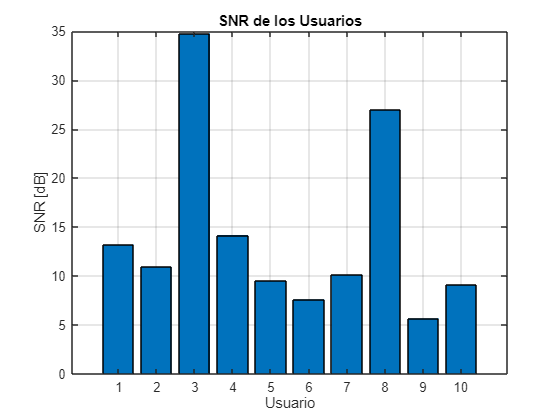

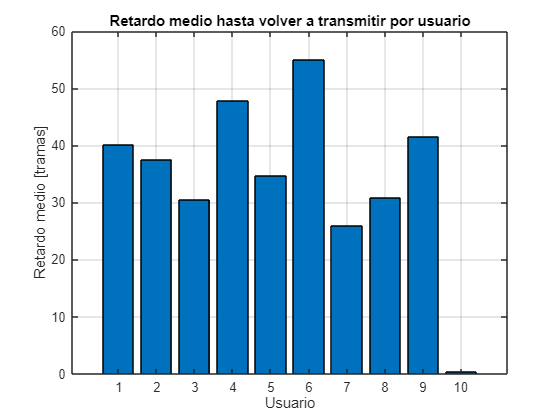

Usuario seleccionado final: 10      Vector de retardo final: 12  30  17   7  14  20  31  13   2   0


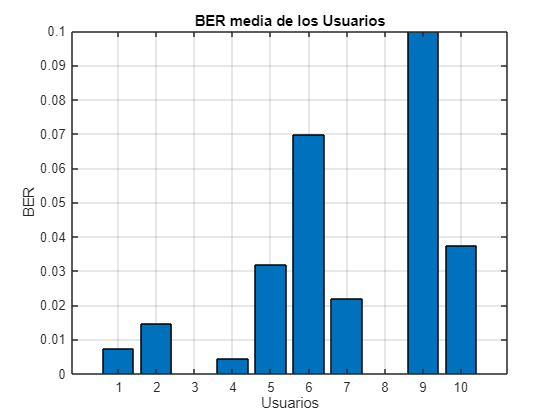

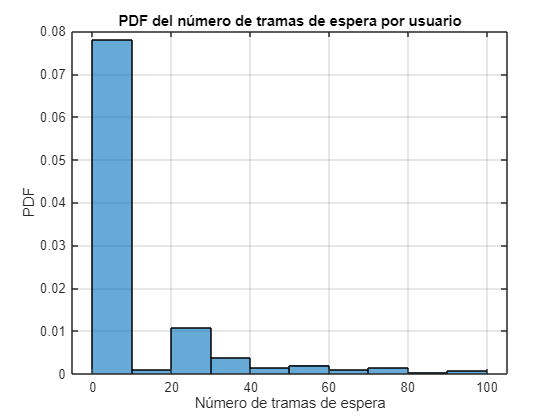

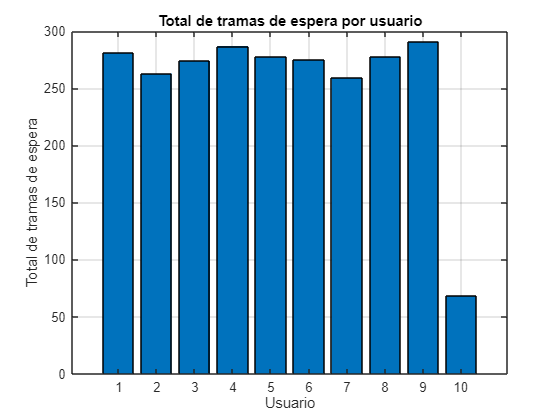

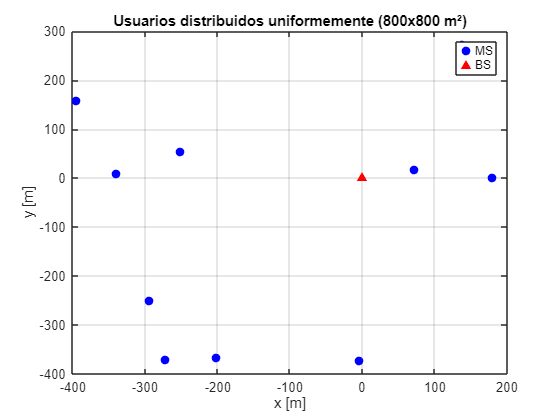

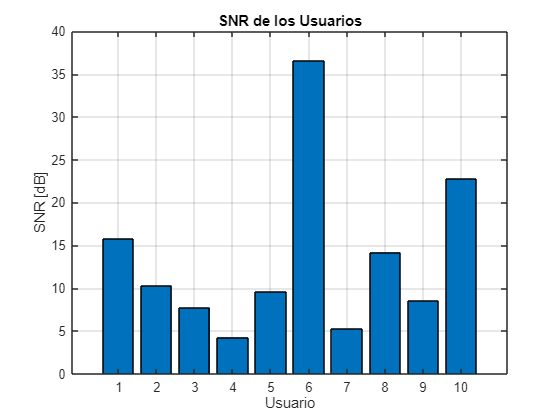

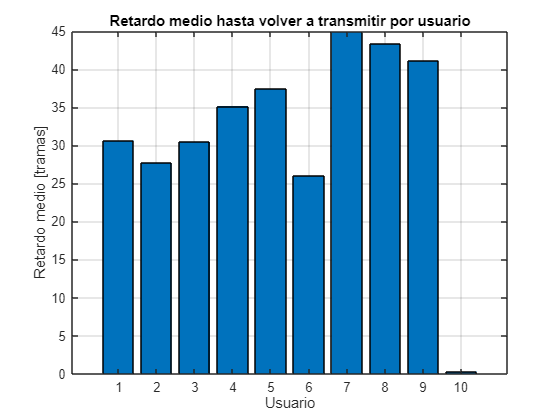

Usuario seleccionado final: 10      Vector de retardo final: 15  13  17  83  31  30  24  34   5   0


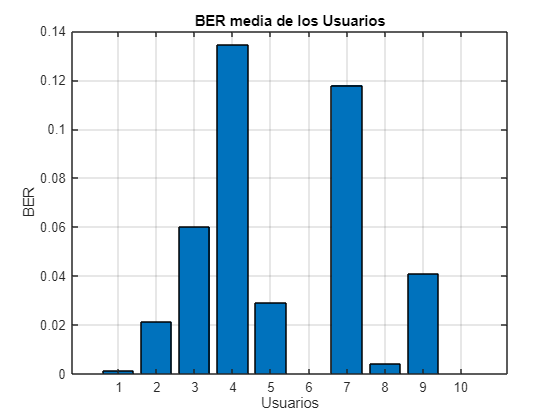

Usuario seleccionado final: 10      Vector de retardo final: 4   9   8  45  58  16  30  18   5   0


Usuario seleccionado final: 10      Vector de retardo final: 18  55   2  35  27  21   5  53  45   0


Usuario seleccionado final: 10      Vector de retardo final: 13  14  20  12  52  36  25   8  16   0


Usuario seleccionado final: 10      Vector de retardo final: 53  97  25  22   5  41  30  45  10   0


Usuario seleccionado final: 10      Vector de retardo final: 32   2  37  21   4   5  14  24  28   0


clear all; clc;

% ---------------------------------------------
% Parámetros del sistema
% ---------------------------------------------

B = 10*10^6;            % Ancho de banda de 10 MHz
f = 1.8*10^9;           % Frecuencia portadora de 1.8 GHz
Ptx = 20;               % Potencia de transmisión en vatios (20 W)
num_muestras = 9600;    % Número total de muestras a simular inicialmente
N0 = 10^-20;            % Densidad espectral de ruido (W/Hz)
sigma_sh = 1.5;         % Desviación típica del shadowing log-normal (dB)
fd_values = [5 50 120]; % Tres valores posibles de frecuencia de Doppler (baja, media, alta)
ts = 1/B;               % Tiempo de símbolo = inverso del ancho de banda
M = 16;                 % Tamaño de la modulación (16QAM)

% ---------------------------------------------
% Ubicación de los usuarios y la estación base
% ---------------------------------------------

Pos_BS = 0 + 1i * 0;    % Estación base ubicada en el origen (coordenadas complejas)

K = 10;                 % Número total de usuarios móviles

% Resultados acumulados para las CDFs
retardos_all = cell(K, 1);
BER_all = cell(K, 1);
tasa_all = cell(K, 1);

nbrofSetups = 10;

% Montecarlo con Frecuencia Doppler = 5 y algoritmo de utilidad
for i = 1:nbrofSetups
    % --------------------------------------
    % Opción 1: Área rectangular 800x800 m
    % --------------------------------------
    lado_x = 800;
    lado_y = 800;
    option1 = 1;
    Pos_MS1 = Calc_Pos_MS(option1, K, 0, 0, lado_x, lado_y);
    
    % -----------------------
    % Visualización
    % -----------------------
    figure;
    plot(real(Pos_MS1), imag(Pos_MS1), 'bo', 'MarkerFaceColor', 'b');
    hold on;
    plot(real(Pos_BS), imag(Pos_BS), 'r^', 'MarkerFaceColor', 'r');
    title('Usuarios distribuidos uniformemente (800x800 m²)');
    xlabel('x [m]'); ylabel('y [m]');
    grid on; legend('MS','BS');
    
    % ---------------------------------------------
    % Cálculo inicial de la SNR de cada usuario
    % ---------------------------------------------
    
    SNRs = zeros(K, 1); % Vector para almacenar la SNR de cada usuario
    
    for k = 1:K
        dist = abs(Pos_BS - Pos_MS1(k)); % Distancia entre BS y usuario k
        SNRs(k) = calcular_SNRs(Pos_BS, Pos_MS1(k), Ptx, B, f, sigma_sh, N0); % Cálculo de SNR
    end

    % ---------------------------------------------
    % Visualización de las SNRs de los usuarios
    % ---------------------------------------------
    figure;
    bar(SNRs); % Representación gráfica en barras
    title('SNR de los Usuarios');
    xlabel('Usuario');
    ylabel('SNR [dB]');
    grid on;

    % ---------------------------------------------
    % Parámetros de simulación y Scheduler
    % ---------------------------------------------
    
    SNR_avg = mean(SNRs); % SNR media de todos los usuarios
    delay_vector = zeros(1, K); % Inicializa el vector de retardos
    num_tramas = num_muestras / 32; % Cada trama representa 32 símbolos
    
    % Casos con algoritmo de utilidad para las distintas frecuencias Doppler
    algoritmo = 'utilidad'; % Algoritmo de planificación

    % --- Simulación con frecuencia de Doppler = 5 Hz ---
    SNR_instantanea = Apply_Rayleigh_Channel(SNRs, fd_values(1), num_muestras, ts);
    SNR_instantanea = SNR_instantanea(:, 1:32:end); % Tomar columnas cada 32 muestras
    
    [selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = ...
        Scheduler(SNR_instantanea, delay_vector, SNR_avg, algoritmo, num_tramas);
    
    plotMeanDelay(retardos);
    disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

    BER_k = Calculate_BER(SNR_instantanea, M);  % Cálculo de BER por usuario

    % Visualización de la BER media de los usuarios
    figure;
    bar(BER_k); % Representación gráfica en barras
    title('BER media de los Usuarios');
    xlabel('Usuarios');
    ylabel('BER');
    grid on;

    % Generación de bits a transmitir
    num_bits = log2(M) * num_muestras; % 4 bits por símbolo
    btx = randi([0 1], K, num_bits);
    
    % Transmisión 16QAM
    [brx, y] = Transmit_16QAM(btx, selected_users, SNR_instantanea, M);

    % Cálculo de la tasa transmitida a cada usuario
    tasa_k = user_tx_count * 32 / (num_muestras / B);  % tasa en Mb/s (aprox)

    % Acumulación por usuario (corregida)
    for k = 1:K
        retardos_all{k} = [retardos_all{k}, retardos{k}];   % concatenar retardos
        BER_all{k} = [BER_all{k}, BER_k(k)];                % concatenar BER media
        tasa_all{k} = [tasa_all{k}, tasa_k(k)];             % concatenar tasa media
    end

    % --- PDF del número total de tramas de espera ---
    all_delays = cell2mat(retardos);  % Unifica todas las celdas

    total_tramas_espera = sum(all_delays);  % Tramas totales de espera
    
    figure;
    histogram(all_delays, 'Normalization', 'pdf');
    xlabel('Número de tramas de espera');
    ylabel('PDF');
    title('PDF del número de tramas de espera por usuario');
    grid on;

    total_delays_per_user = cellfun(@sum, retardos);
    
    figure;
    bar(1:K, total_delays_per_user);
    xlabel('Usuario');
    ylabel('Total de tramas de espera');
    title('Total de tramas de espera por usuario');
    grid on;
end

% --- CDF del retardo medio por usuario ---
% Cada celda de retardos_all{k} contiene los retardos acumulados del usuario k
retardo_medio_por_usuario = cellfun(@mean, retardos_all);     
retardo_ordenado = sort(retardo_medio_por_usuario);
cdf_retardo = linspace(0, 1, length(retardo_ordenado));
figure;
plot(retardo_ordenado, cdf_retardo, 'r-', 'LineWidth', 2);
xlabel('Retardo medio [tramas]');
ylabel('CDF');
title('CDF del retardo medio por usuario');
grid on;
ylim([0 1]);

% --- CDF de la BER media por usuario ---
% Cada celda de BER_all{k} contiene las BERs acumuladas del usuario k
ber_media_por_usuario = cellfun(@mean, BER_all);              
ber_ordenado = sort(ber_media_por_usuario);
cdf_ber = linspace(0, 1, length(ber_ordenado));
figure;
plot(ber_ordenado, cdf_ber, 'b-', 'LineWidth', 2);
xlabel('BER Media');
ylabel('CDF');
title('CDF de la BER media por usuario');
grid on;
ylim([0 1]);

% --- CDF de la tasa transmitida por usuario ---
% Cada celda de tasa_all{k} contiene las tasas acumuladas del usuario k
tasa_media_por_usuario = cellfun(@mean, tasa_all);           
tasa_ordenada = sort(tasa_media_por_usuario);
cdf_tasa = linspace(0, 1, length(tasa_ordenada));
figure;
plot(tasa_ordenada, cdf_tasa, 'k-', 'LineWidth', 2);
xlabel('Tasa transmitida por usuario [Mb/s]');
ylabel('CDF');
title('CDF de la tasa transmitida por usuario');
grid on;
ylim([0 1]);

%Inicializo las variables nuevamente para realizar las futuras simulaciones
retardos_all = cell(K, 1);   
BER_all = cell(K, 1);        
tasa_all = cell(K, 1);       
delay_vector = zeros(1, K);  
selected_users = [];
user_tx_count = zeros(1, K);

% Montecarlo con Frecuencia Doppler = 50 y algoritmo de utilidad
for i = 1:nbrofSetups
    % --------------------------------------
    % Opción 1: Área rectangular 800x800 m
    % --------------------------------------
    lado_x = 800;
    lado_y = 800;
    option1 = 1;
    Pos_MS1 = Calc_Pos_MS(option1, K, 0, 0, lado_x, lado_y);
    
    % -----------------------
    % Visualización
    % -----------------------
    figure;
    plot(real(Pos_MS1), imag(Pos_MS1), 'bo', 'MarkerFaceColor', 'b');
    hold on;
    plot(real(Pos_BS), imag(Pos_BS), 'r^', 'MarkerFaceColor', 'r');
    title('Usuarios distribuidos uniformemente (800x800 m²)');
    xlabel('x [m]'); ylabel('y [m]');
    grid on; legend('MS','BS');
    
    % ---------------------------------------------
    % Cálculo inicial de la SNR de cada usuario
    % ---------------------------------------------
    
    SNRs = zeros(K, 1); % Vector para almacenar la SNR de cada usuario
    
    for k = 1:K
        dist = abs(Pos_BS - Pos_MS1(k)); % Distancia entre BS y usuario k
        SNRs(k) = calcular_SNRs(Pos_BS, Pos_MS1(k), Ptx, B, f, sigma_sh, N0); % Cálculo de SNR
    end

    % ---------------------------------------------
    % Visualización de las SNRs de los usuarios
    % ---------------------------------------------
    figure;
    bar(SNRs); % Representación gráfica en barras
    title('SNR de los Usuarios');
    xlabel('Usuario');
    ylabel('SNR [dB]');
    grid on;

    % ---------------------------------------------
    % Parámetros de simulación y Scheduler
    % ---------------------------------------------
    
    SNR_avg = mean(SNRs); % SNR media de todos los usuarios
    delay_vector = zeros(1, K); % Inicializa el vector de retardos
    num_tramas = num_muestras / 32; % Cada trama representa 32 símbolos
    
    % Casos con algoritmo de utilidad para las distintas frecuencias Doppler
    algoritmo = 'utilidad'; % Algoritmo de planificación

    % --- Simulación con frecuencia de Doppler = 50 Hz ---
    SNR_instantanea = Apply_Rayleigh_Channel(SNRs, fd_values(2), num_muestras, ts);
    SNR_instantanea = SNR_instantanea(:, 1:32:end); % Tomar columnas cada 32 muestras
    
    [selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = ...
        Scheduler(SNR_instantanea, delay_vector, SNR_avg, algoritmo, num_tramas);
    
    plotMeanDelay(retardos);
    disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

    BER_k = Calculate_BER(SNR_instantanea, M);  % Cálculo de BER por usuario

    % Visualización de la BER media de los usuarios
    figure;
    bar(BER_k); % Representación gráfica en barras
    title('BER media de los Usuarios');
    xlabel('Usuarios');
    ylabel('BER');
    grid on;

    % Generación de bits a transmitir
    num_bits = log2(M) * num_muestras; % 4 bits por símbolo
    btx = randi([0 1], K, num_bits);
    
    % Transmisión 16QAM
    [brx, y] = Transmit_16QAM(btx, selected_users, SNR_instantanea, M);

    % Cálculo de la tasa transmitida a cada usuario
    tasa_k = user_tx_count * 32 / (num_muestras / B);  % tasa en Mb/s (aprox)

    % Acumulación por usuario (corregida)
    for k = 1:K
        retardos_all{k} = [retardos_all{k}, retardos{k}];   % concatenar retardos
        BER_all{k} = [BER_all{k}, BER_k(k)];                % concatenar BER media
        tasa_all{k} = [tasa_all{k}, tasa_k(k)];             % concatenar tasa media
    end

    % --- PDF del número total de tramas de espera ---
    all_delays = cell2mat(retardos);  % Unifica todas las celdas

    total_tramas_espera = sum(all_delays);  % Tramas totales de espera
    
    figure;
    histogram(all_delays, 'Normalization', 'pdf');
    xlabel('Número de tramas de espera');
    ylabel('PDF');
    title('PDF del número de tramas de espera por usuario');
    grid on;

    total_delays_per_user = cellfun(@sum, retardos);
    
    figure;
    bar(1:K, total_delays_per_user);
    xlabel('Usuario');
    ylabel('Total de tramas de espera');
    title('Total de tramas de espera por usuario');
    grid on;
end

% --- CDF del retardo medio por usuario ---
% Cada celda de retardos_all{k} contiene los retardos acumulados del usuario k
retardo_medio_por_usuario = cellfun(@mean, retardos_all);     
retardo_ordenado = sort(retardo_medio_por_usuario);
cdf_retardo = linspace(0, 1, length(retardo_ordenado));
figure;
plot(retardo_ordenado, cdf_retardo, 'r-', 'LineWidth', 2);
xlabel('Retardo medio [tramas]');
ylabel('CDF');
title('CDF del retardo medio por usuario');
grid on;
ylim([0 1]);

% --- CDF de la BER media por usuario ---
% Cada celda de BER_all{k} contiene las BERs acumuladas del usuario k
ber_media_por_usuario = cellfun(@mean, BER_all);              
ber_ordenado = sort(ber_media_por_usuario);
cdf_ber = linspace(0, 1, length(ber_ordenado));
figure;
plot(ber_ordenado, cdf_ber, 'b-', 'LineWidth', 2);
xlabel('BER Media');
ylabel('CDF');
title('CDF de la BER media por usuario');
grid on;
ylim([0 1]);

% --- CDF de la tasa transmitida por usuario ---
% Cada celda de tasa_all{k} contiene las tasas acumuladas del usuario k
tasa_media_por_usuario = cellfun(@mean, tasa_all);           
tasa_ordenada = sort(tasa_media_por_usuario);
cdf_tasa = linspace(0, 1, length(tasa_ordenada));
figure;
plot(tasa_ordenada, cdf_tasa, 'k-', 'LineWidth', 2);
xlabel('Tasa transmitida por usuario [Mb/s]');
ylabel('CDF');
title('CDF de la tasa transmitida por usuario');
grid on;
ylim([0 1]);

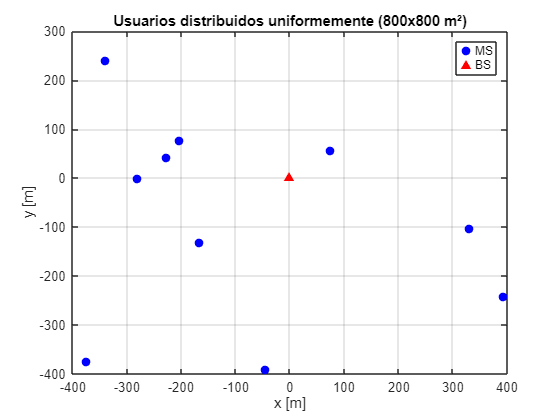

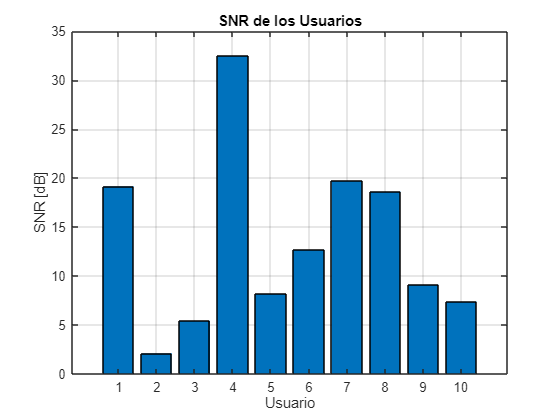

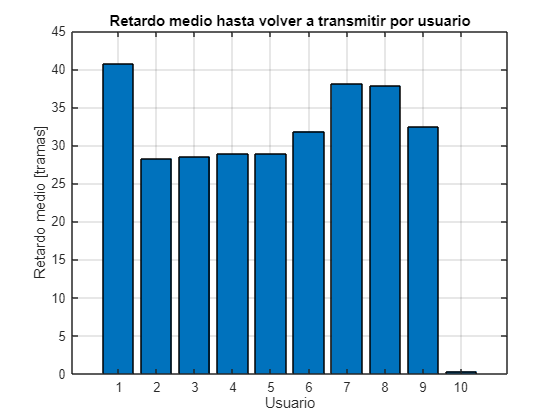

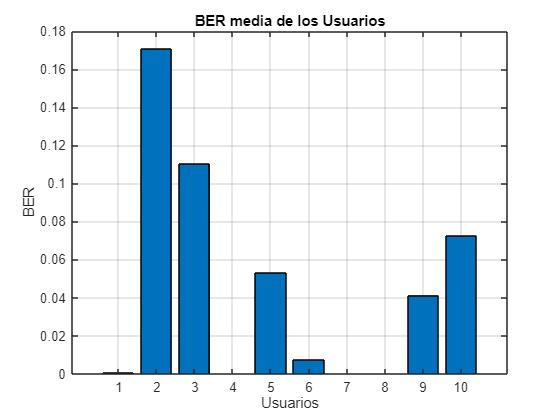

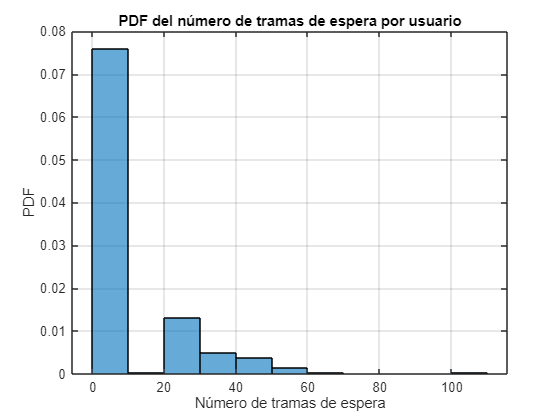

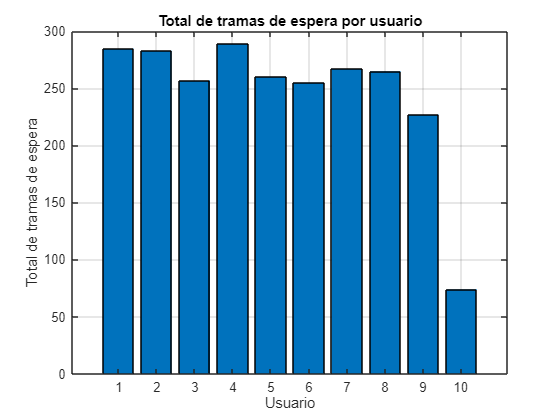

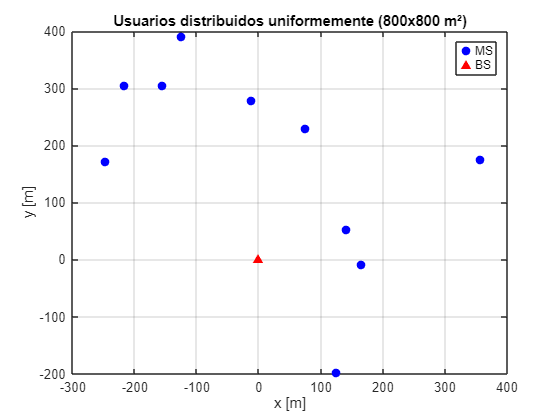

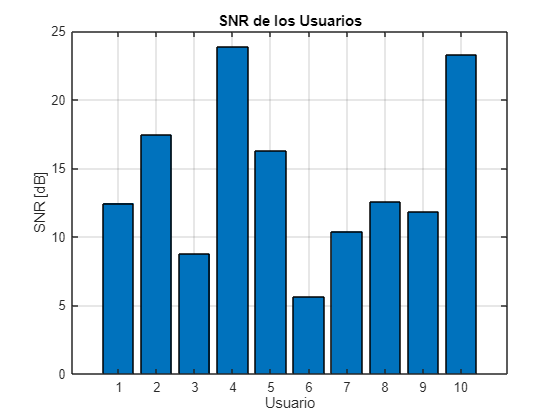

%Inicializo las variables nuevamente para realizar las futuras simulaciones
retardos_all = cell(K, 1);   
BER_all = cell(K, 1);        
tasa_all = cell(K, 1);       
delay_vector = zeros(1, K);  
selected_users = [];
user_tx_count = zeros(1, K);

% Montecarlo con Frecuencia Doppler = 120 y algoritmo de utilidad
for i = 1:nbrofSetups
    % --------------------------------------
    % Opción 1: Área rectangular 800x800 m
    % --------------------------------------
    lado_x = 800;
    lado_y = 800;
    option1 = 1;
    Pos_MS1 = Calc_Pos_MS(option1, K, 0, 0, lado_x, lado_y);
    
    % -----------------------
    % Visualización
    % -----------------------
    figure;
    plot(real(Pos_MS1), imag(Pos_MS1), 'bo', 'MarkerFaceColor', 'b');
    hold on;
    plot(real(Pos_BS), imag(Pos_BS), 'r^', 'MarkerFaceColor', 'r');
    title('Usuarios distribuidos uniformemente (800x800 m²)');
    xlabel('x [m]'); ylabel('y [m]');
    grid on; legend('MS','BS');
    
    % ---------------------------------------------
    % Cálculo inicial de la SNR de cada usuario
    % ---------------------------------------------
    
    SNRs = zeros(K, 1); % Vector para almacenar la SNR de cada usuario
    
    for k = 1:K
        dist = abs(Pos_BS - Pos_MS1(k)); % Distancia entre BS y usuario k
        SNRs(k) = calcular_SNRs(Pos_BS, Pos_MS1(k), Ptx, B, f, sigma_sh, N0); % Cálculo de SNR
    end

    % ---------------------------------------------
    % Visualización de las SNRs de los usuarios
    % ---------------------------------------------
    figure;
    bar(SNRs); % Representación gráfica en barras
    title('SNR de los Usuarios');
    xlabel('Usuario');
    ylabel('SNR [dB]');
    grid on;

    % ---------------------------------------------
    % Parámetros de simulación y Scheduler
    % ---------------------------------------------
    
    SNR_avg = mean(SNRs); % SNR media de todos los usuarios
    delay_vector = zeros(1, K); % Inicializa el vector de retardos
    num_tramas = num_muestras / 32; % Cada trama representa 32 símbolos
    
    % Casos con algoritmo de utilidad para las distintas frecuencias Doppler
    algoritmo = 'utilidad'; % Algoritmo de planificación

    % --- Simulación con frecuencia de Doppler = 120 Hz ---
    SNR_instantanea = Apply_Rayleigh_Channel(SNRs, fd_values(3), num_muestras, ts);
    SNR_instantanea = SNR_instantanea(:, 1:32:end); % Tomar columnas cada 32 muestras
    
    [selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = ...
        Scheduler(SNR_instantanea, delay_vector, SNR_avg, algoritmo, num_tramas);
    
    plotMeanDelay(retardos);
    disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

    BER_k = Calculate_BER(SNR_instantanea, M);  % Cálculo de BER por usuario

    % Visualización de la BER media de los usuarios
    figure;
    bar(BER_k); % Representación gráfica en barras
    title('BER media de los Usuarios');
    xlabel('Usuarios');
    ylabel('BER');
    grid on;

    % Generación de bits a transmitir
    num_bits = log2(M) * num_muestras; % 4 bits por símbolo
    btx = randi([0 1], K, num_bits);
    
    % Transmisión 16QAM
    [brx, y] = Transmit_16QAM(btx, selected_users, SNR_instantanea, M);

    % Cálculo de la tasa transmitida a cada usuario
    tasa_k = user_tx_count * 32 / (num_muestras / B);  % tasa en Mb/s (aprox)

    % Acumulación por usuario (corregida)
    for k = 1:K
        retardos_all{k} = [retardos_all{k}, retardos{k}];   % concatenar retardos
        BER_all{k} = [BER_all{k}, BER_k(k)];                % concatenar BER media
        tasa_all{k} = [tasa_all{k}, tasa_k(k)];             % concatenar tasa media
    end

    % --- PDF del número total de tramas de espera ---
    all_delays = cell2mat(retardos);  % Unifica todas las celdas

    total_tramas_espera = sum(all_delays);  % Tramas totales de espera
    
    figure;
    histogram(all_delays, 'Normalization', 'pdf');
    xlabel('Número de tramas de espera');
    ylabel('PDF');
    title('PDF del número de tramas de espera por usuario');
    grid on;

    total_delays_per_user = cellfun(@sum, retardos);
    
    figure;
    bar(1:K, total_delays_per_user);
    xlabel('Usuario');
    ylabel('Total de tramas de espera');
    title('Total de tramas de espera por usuario');
    grid on;
end

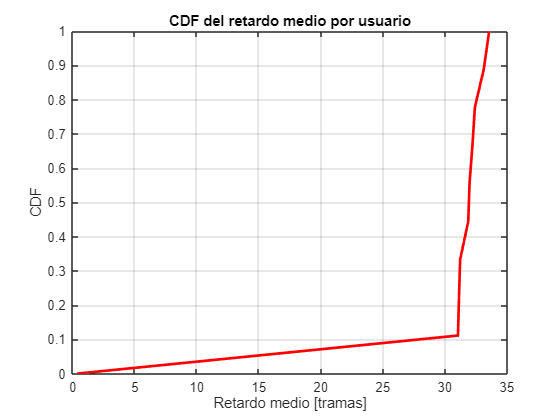


% --- CDF del retardo medio por usuario ---
% Cada celda de retardos_all{k} contiene los retardos acumulados del usuario k
retardo_medio_por_usuario = cellfun(@mean, retardos_all);     
retardo_ordenado = sort(retardo_medio_por_usuario);
cdf_retardo = linspace(0, 1, length(retardo_ordenado));
figure;
plot(retardo_ordenado, cdf_retardo, 'r-', 'LineWidth', 2);
xlabel('Retardo medio [tramas]');
ylabel('CDF');
title('CDF del retardo medio por usuario');
grid on;
ylim([0 1]);

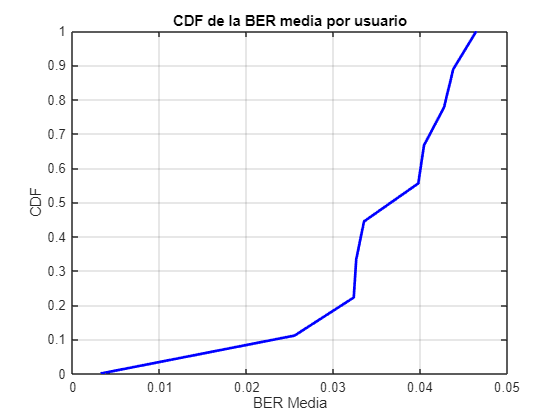


% --- CDF de la BER media por usuario ---
% Cada celda de BER_all{k} contiene las BERs acumuladas del usuario k
ber_media_por_usuario = cellfun(@mean, BER_all);              
ber_ordenado = sort(ber_media_por_usuario);
cdf_ber = linspace(0, 1, length(ber_ordenado));
figure;
plot(ber_ordenado, cdf_ber, 'b-', 'LineWidth', 2);
xlabel('BER Media');
ylabel('CDF');
title('CDF de la BER media por usuario');
grid on;
ylim([0 1]);

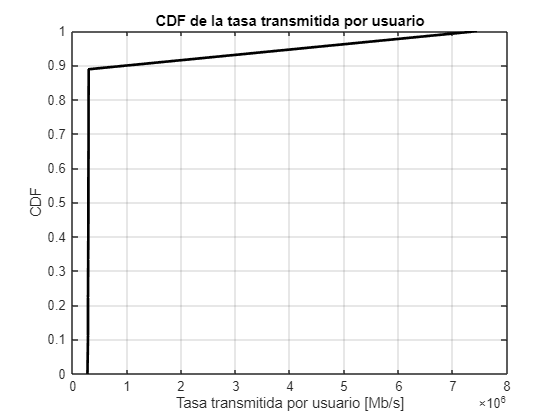


% --- CDF de la tasa transmitida por usuario ---
% Cada celda de tasa_all{k} contiene las tasas acumuladas del usuario k
tasa_media_por_usuario = cellfun(@mean, tasa_all);           
tasa_ordenada = sort(tasa_media_por_usuario);
cdf_tasa = linspace(0, 1, length(tasa_ordenada));
figure;
plot(tasa_ordenada, cdf_tasa, 'k-', 'LineWidth', 2);
xlabel('Tasa transmitida por usuario [Mb/s]');
ylabel('CDF');
title('CDF de la tasa transmitida por usuario');
grid on;
ylim([0 1]);

%SIMULACIONES CON LAS DISTINTAS FRECUENCIAS DOPPLER Y EL ALGORITMO DE MAXSNR
%Inicializo las variables nuevamente para realizar las futuras simulaciones
retardos_all = cell(K, 1);   
BER_all = cell(K, 1);        
tasa_all = cell(K, 1);       
delay_vector = zeros(1, K);  
selected_users = [];
user_tx_count = zeros(1, K);

% Montecarlo con Frecuencia Doppler = 5 y algoritmo de maxsnr
for i = 1:nbrofSetups
    % --------------------------------------
    % Opción 1: Área rectangular 800x800 m
    % --------------------------------------
    lado_x = 800;
    lado_y = 800;
    option1 = 1;
    Pos_MS1 = Calc_Pos_MS(option1, K, 0, 0, lado_x, lado_y);
    
    % -----------------------
    % Visualización
    % -----------------------
    figure;
    plot(real(Pos_MS1), imag(Pos_MS1), 'bo', 'MarkerFaceColor', 'b');
    hold on;
    plot(real(Pos_BS), imag(Pos_BS), 'r^', 'MarkerFaceColor', 'r');
    title('Usuarios distribuidos uniformemente (800x800 m²)');
    xlabel('x [m]'); ylabel('y [m]');
    grid on; legend('MS','BS');
    
    % ---------------------------------------------
    % Cálculo inicial de la SNR de cada usuario
    % ---------------------------------------------
    
    SNRs = zeros(K, 1); % Vector para almacenar la SNR de cada usuario
    
    for k = 1:K
        dist = abs(Pos_BS - Pos_MS1(k)); % Distancia entre BS y usuario k
        SNRs(k) = calcular_SNRs(Pos_BS, Pos_MS1(k), Ptx, B, f, sigma_sh, N0); % Cálculo de SNR
    end

    % ---------------------------------------------
    % Visualización de las SNRs de los usuarios
    % ---------------------------------------------
    figure;
    bar(SNRs); % Representación gráfica en barras
    title('SNR de los Usuarios');
    xlabel('Usuario');
    ylabel('SNR [dB]');
    grid on;

    % ---------------------------------------------
    % Parámetros de simulación y Scheduler
    % ---------------------------------------------
    
    SNR_avg = mean(SNRs); % SNR media de todos los usuarios
    delay_vector = zeros(1, K); % Inicializa el vector de retardos
    num_tramas = num_muestras / 32; % Cada trama representa 32 símbolos
    
    % Casos con algoritmo de utilidad para las distintas frecuencias Doppler
    algoritmo = 'maxsnr'; % Algoritmo de planificación

    % --- Simulación con frecuencia de Doppler = 5 Hz ---
    SNR_instantanea = Apply_Rayleigh_Channel(SNRs, fd_values(1), num_muestras, ts);
    SNR_instantanea = SNR_instantanea(:, 1:32:end); % Tomar columnas cada 32 muestras
    
    [selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = ...
        Scheduler(SNR_instantanea, delay_vector, SNR_avg, algoritmo, num_tramas);
    
    plotMeanDelay(retardos);
    disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

    BER_k = Calculate_BER(SNR_instantanea, M);  % Cálculo de BER por usuario

    % Visualización de la BER media de los usuarios
    figure;
    bar(BER_k); % Representación gráfica en barras
    title('BER media de los Usuarios');
    xlabel('Usuarios');
    ylabel('BER');
    grid on;

    % Generación de bits a transmitir
    num_bits = log2(M) * num_muestras; % 4 bits por símbolo
    btx = randi([0 1], K, num_bits);
    
    % Transmisión 16QAM
    [brx, y] = Transmit_16QAM(btx, selected_users, SNR_instantanea, M);

    % Cálculo de la tasa transmitida a cada usuario
    tasa_k = user_tx_count * 32 / (num_muestras / B);  % tasa en Mb/s (aprox)

    % Acumulación por usuario (corregida)
    for k = 1:K
        retardos_all{k} = [retardos_all{k}, retardos{k}];   % concatenar retardos
        BER_all{k} = [BER_all{k}, BER_k(k)];                % concatenar BER media
        tasa_all{k} = [tasa_all{k}, tasa_k(k)];             % concatenar tasa media
    end

    % --- PDF del número total de tramas de espera ---
    all_delays = cell2mat(retardos);  % Unifica todas las celdas

    total_tramas_espera = sum(all_delays);  % Tramas totales de espera
    
    figure;
    histogram(all_delays, 'Normalization', 'pdf');
    xlabel('Número de tramas de espera');
    ylabel('PDF');
    title('PDF del número de tramas de espera por usuario');
    grid on;

    total_delays_per_user = cellfun(@sum, retardos);
    
    figure;
    bar(1:K, total_delays_per_user);
    xlabel('Usuario');
    ylabel('Total de tramas de espera');
    title('Total de tramas de espera por usuario');
    grid on;
end

Usuario seleccionado final: 2      Vector de retardo final: 7    0  300  300  300  300    3  223  300  300


Usuario seleccionado final: 5      Vector de retardo final: 36  300  300  300    0  300  300  300  300  300


Usuario seleccionado final: 1      Vector de retardo final: 0  300  300   23  300  300  300  300  300  300


Usuario seleccionado final: 10      Vector de retardo final: 300  300  300  300   11  300  300  300  300    0


Usuario seleccionado final: 10      Vector de retardo final: 300  300   43    1  246  300  300    2  300    0


Usuario seleccionado final: 8      Vector de retardo final: 300   78  300  106  300  300  300    0  300    4


Usuario seleccionado final: 10      Vector de retardo final: 300  300  300  300  300  300    1  300  300    0


Usuario seleccionado final: 1      Vector de retardo final: 0  300    6  233  300  300  300  300  300  300


Usuario seleccionado final: 7      Vector de retardo final: 300  300  300  300  300  300    0  300  300  300


Usuario seleccionado final: 7      Vector de retardo final: 300  300  300  300  300  300    0  300  300  300



% --- CDF del retardo medio por usuario ---
% Cada celda de retardos_all{k} contiene los retardos acumulados del usuario k
retardo_medio_por_usuario = cellfun(@mean, retardos_all);     
retardo_ordenado = sort(retardo_medio_por_usuario);
cdf_retardo = linspace(0, 1, length(retardo_ordenado));
figure;
plot(retardo_ordenado, cdf_retardo, 'r-', 'LineWidth', 2);
xlabel('Retardo medio [tramas]');
ylabel('CDF');
title('CDF del retardo medio por usuario');
grid on;
ylim([0 1]);


% --- CDF de la BER media por usuario ---
% Cada celda de BER_all{k} contiene las BERs acumuladas del usuario k
ber_media_por_usuario = cellfun(@mean, BER_all);              
ber_ordenado = sort(ber_media_por_usuario);
cdf_ber = linspace(0, 1, length(ber_ordenado));
figure;
plot(ber_ordenado, cdf_ber, 'b-', 'LineWidth', 2);
xlabel('BER Media');
ylabel('CDF');
title('CDF de la BER media por usuario');
grid on;
ylim([0 1]);


% --- CDF de la tasa transmitida por usuario ---
% Cada celda de tasa_all{k} contiene las tasas acumuladas del usuario k
tasa_media_por_usuario = cellfun(@mean, tasa_all);           
tasa_ordenada = sort(tasa_media_por_usuario);
cdf_tasa = linspace(0, 1, length(tasa_ordenada));
figure;
plot(tasa_ordenada, cdf_tasa, 'k-', 'LineWidth', 2);
xlabel('Tasa transmitida por usuario [Mb/s]');
ylabel('CDF');
title('CDF de la tasa transmitida por usuario');
grid on;
ylim([0 1]);

%Inicializo las variables nuevamente para realizar las futuras simulaciones
retardos_all = cell(K, 1);   
BER_all = cell(K, 1);        
tasa_all = cell(K, 1);       
delay_vector = zeros(1, K);  
selected_users = [];
user_tx_count = zeros(1, K);

% Montecarlo con Frecuencia Doppler = 50 y algoritmo de maxsnr
for i = 1:nbrofSetups
    % --------------------------------------
    % Opción 1: Área rectangular 800x800 m
    % --------------------------------------
    lado_x = 800;
    lado_y = 800;
    option1 = 1;
    Pos_MS1 = Calc_Pos_MS(option1, K, 0, 0, lado_x, lado_y);
    
    % -----------------------
    % Visualización
    % -----------------------
    figure;
    plot(real(Pos_MS1), imag(Pos_MS1), 'bo', 'MarkerFaceColor', 'b');
    hold on;
    plot(real(Pos_BS), imag(Pos_BS), 'r^', 'MarkerFaceColor', 'r');
    title('Usuarios distribuidos uniformemente (800x800 m²)');
    xlabel('x [m]'); ylabel('y [m]');
    grid on; legend('MS','BS');
    
    % ---------------------------------------------
    % Cálculo inicial de la SNR de cada usuario
    % ---------------------------------------------
    
    SNRs = zeros(K, 1); % Vector para almacenar la SNR de cada usuario
    
    for k = 1:K
        dist = abs(Pos_BS - Pos_MS1(k)); % Distancia entre BS y usuario k
        SNRs(k) = calcular_SNRs(Pos_BS, Pos_MS1(k), Ptx, B, f, sigma_sh, N0); % Cálculo de SNR
    end

    % ---------------------------------------------
    % Visualización de las SNRs de los usuarios
    % ---------------------------------------------
    figure;
    bar(SNRs); % Representación gráfica en barras
    title('SNR de los Usuarios');
    xlabel('Usuario');
    ylabel('SNR [dB]');
    grid on;

    % ---------------------------------------------
    % Parámetros de simulación y Scheduler
    % ---------------------------------------------
    
    SNR_avg = mean(SNRs); % SNR media de todos los usuarios
    delay_vector = zeros(1, K); % Inicializa el vector de retardos
    num_tramas = num_muestras / 32; % Cada trama representa 32 símbolos
    
    % Casos con algoritmo de utilidad para las distintas frecuencias Doppler
    algoritmo = 'maxsnr'; % Algoritmo de planificación

    % --- Simulación con frecuencia de Doppler = 50 Hz ---
    SNR_instantanea = Apply_Rayleigh_Channel(SNRs, fd_values(2), num_muestras, ts);
    SNR_instantanea = SNR_instantanea(:, 1:32:end); % Tomar columnas cada 32 muestras
    
    [selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = ...
        Scheduler(SNR_instantanea, delay_vector, SNR_avg, algoritmo, num_tramas);
    
    plotMeanDelay(retardos);
    disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

    BER_k = Calculate_BER(SNR_instantanea, M);  % Cálculo de BER por usuario

    % Visualización de la BER media de los usuarios
    figure;
    bar(BER_k); % Representación gráfica en barras
    title('BER media de los Usuarios');
    xlabel('Usuarios');
    ylabel('BER');
    grid on;

    % Generación de bits a transmitir
    num_bits = log2(M) * num_muestras; % 4 bits por símbolo
    btx = randi([0 1], K, num_bits);
    
    % Transmisión 16QAM
    [brx, y] = Transmit_16QAM(btx, selected_users, SNR_instantanea, M);

    % Cálculo de la tasa transmitida a cada usuario
    tasa_k = user_tx_count * 32 / (num_muestras / B);  % tasa en Mb/s (aprox)

    % Acumulación por usuario (corregida)
    for k = 1:K
        retardos_all{k} = [retardos_all{k}, retardos{k}];   % concatenar retardos
        BER_all{k} = [BER_all{k}, BER_k(k)];                % concatenar BER media
        tasa_all{k} = [tasa_all{k}, tasa_k(k)];             % concatenar tasa media
    end

    % --- PDF del número total de tramas de espera ---
    all_delays = cell2mat(retardos);  % Unifica todas las celdas

    total_tramas_espera = sum(all_delays);  % Tramas totales de espera
    
    figure;
    histogram(all_delays, 'Normalization', 'pdf');
    xlabel('Número de tramas de espera');
    ylabel('PDF');
    title('PDF del número de tramas de espera por usuario');
    grid on;

    total_delays_per_user = cellfun(@sum, retardos);
    
    figure;
    bar(1:K, total_delays_per_user);
    xlabel('Usuario');
    ylabel('Total de tramas de espera');
    title('Total de tramas de espera por usuario');
    grid on;
end

Usuario seleccionado final: 7      Vector de retardo final: 300  300  300  300   77  300    0  300   35  300


Usuario seleccionado final: 8      Vector de retardo final: 300  300   40  300  300  300  300    0  300    8


Usuario seleccionado final: 7      Vector de retardo final: 1  300  300  300  300  300    0   28  300  300


Usuario seleccionado final: 10      Vector de retardo final: 300  300  300  300  300  300  300  300  300    0


Usuario seleccionado final: 8      Vector de retardo final: 300   33  300  300  300  300  296    0  300  300


Usuario seleccionado final: 4      Vector de retardo final: 2  300  300    0  300  300  300  157  300  300


Usuario seleccionado final: 4      Vector de retardo final: 300  300  300    0  300  300  300  300  300  300


Usuario seleccionado final: 10      Vector de retardo final: 300  300  300  300  300  300  300  300  300    0


Usuario seleccionado final: 10      Vector de retardo final: 8   52  300   14  300  300  300  300  300    0


Usuario seleccionado final: 9      Vector de retardo final: 300  300  300  300  300  300    2  300    0  300



% --- CDF del retardo medio por usuario ---
% Cada celda de retardos_all{k} contiene los retardos acumulados del usuario k
retardo_medio_por_usuario = cellfun(@mean, retardos_all);     
retardo_ordenado = sort(retardo_medio_por_usuario);
cdf_retardo = linspace(0, 1, length(retardo_ordenado));
figure;
plot(retardo_ordenado, cdf_retardo, 'r-', 'LineWidth', 2);
xlabel('Retardo medio [tramas]');
ylabel('CDF');
title('CDF del retardo medio por usuario');
grid on;
ylim([0 1]);

% --- CDF de la BER media por usuario ---
% Cada celda de BER_all{k} contiene las BERs acumuladas del usuario k
ber_media_por_usuario = cellfun(@mean, BER_all);              
ber_ordenado = sort(ber_media_por_usuario);
cdf_ber = linspace(0, 1, length(ber_ordenado));
figure;
plot(ber_ordenado, cdf_ber, 'b-', 'LineWidth', 2);
xlabel('BER Media');
ylabel('CDF');
title('CDF de la BER media por usuario');
grid on;
ylim([0 1]);

% --- CDF de la tasa transmitida por usuario ---
% Cada celda de tasa_all{k} contiene las tasas acumuladas del usuario k
tasa_media_por_usuario = cellfun(@mean, tasa_all);           
tasa_ordenada = sort(tasa_media_por_usuario);
cdf_tasa = linspace(0, 1, length(tasa_ordenada));
figure;
plot(tasa_ordenada, cdf_tasa, 'k-', 'LineWidth', 2);
xlabel('Tasa transmitida por usuario [Mb/s]');
ylabel('CDF');
title('CDF de la tasa transmitida por usuario');
grid on;
ylim([0 1]);


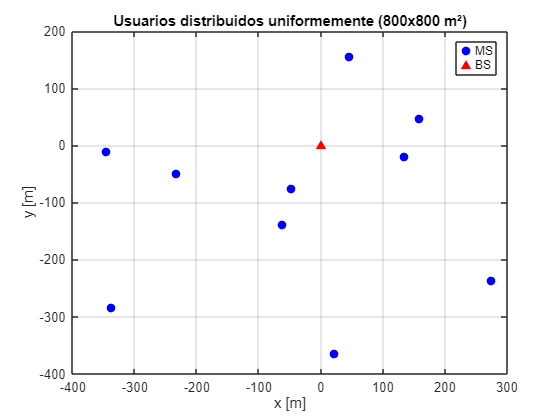

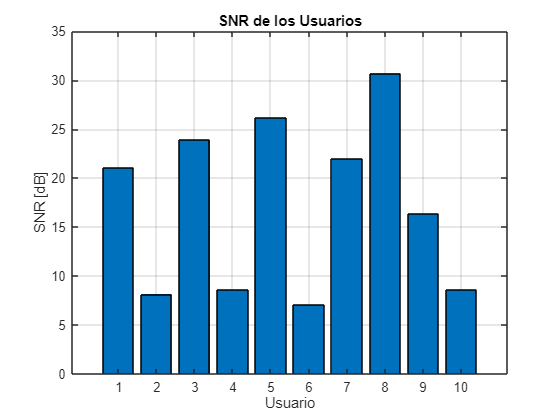

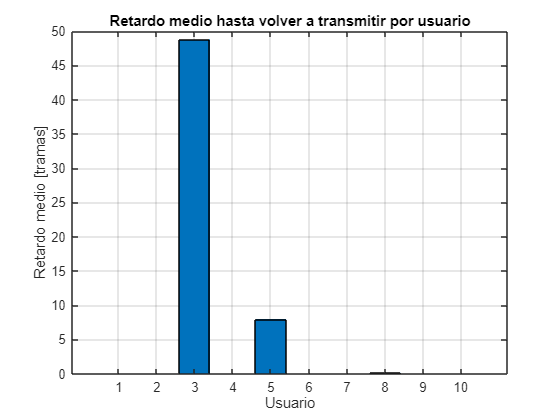

Usuario seleccionado final: 8      Vector de retardo final: 300  300    1  300   22  300  300    0  300  300


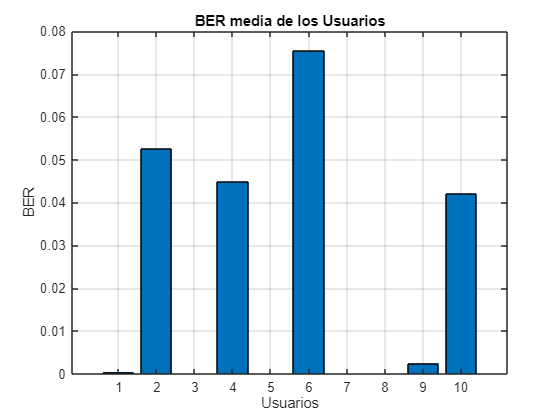

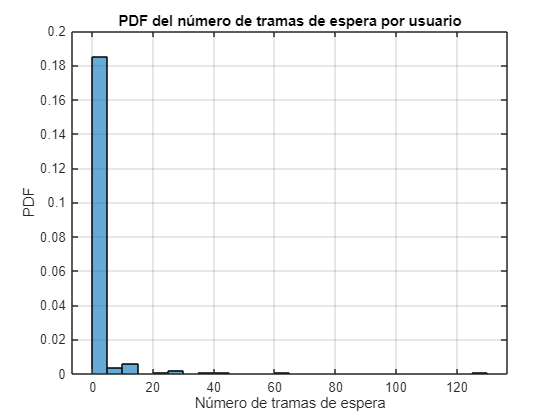

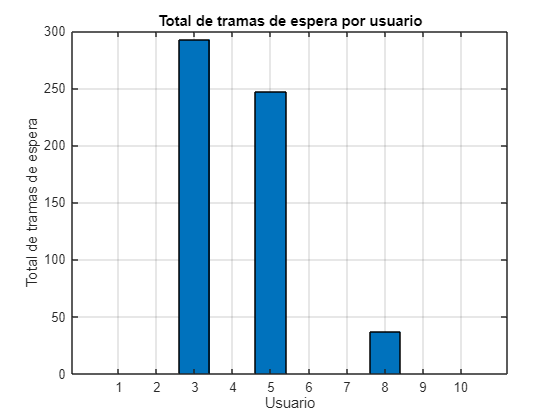

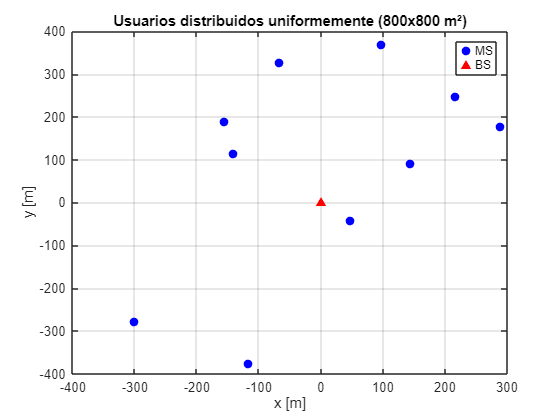

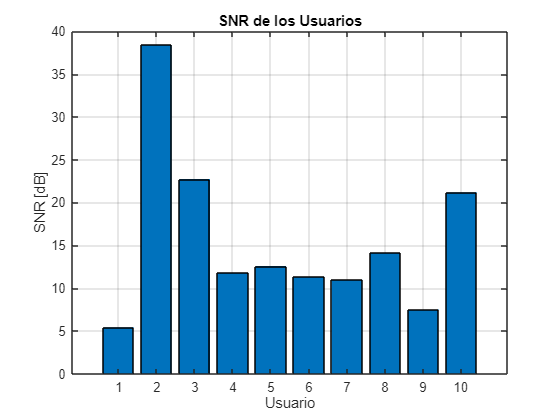

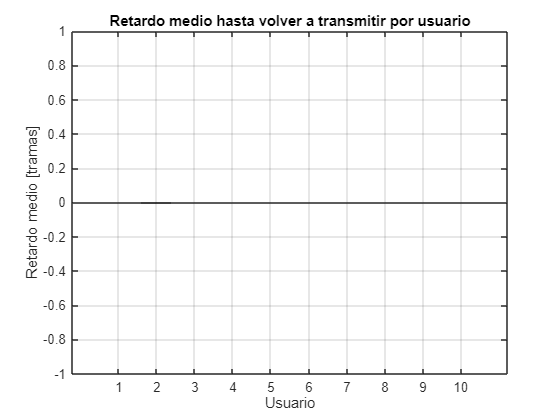

Usuario seleccionado final: 2      Vector de retardo final: 300    0  300  300  300  300  300  300  300  300


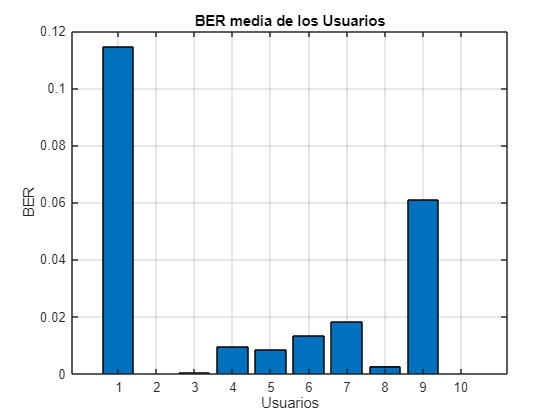

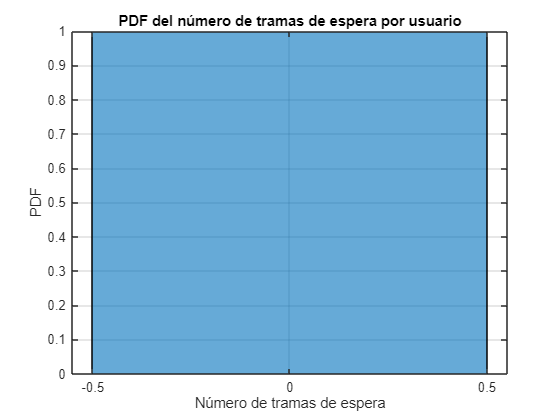

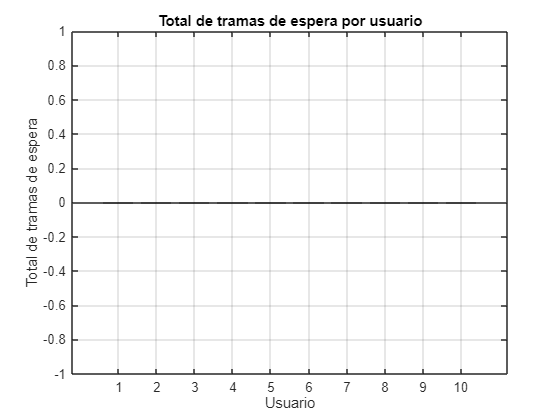

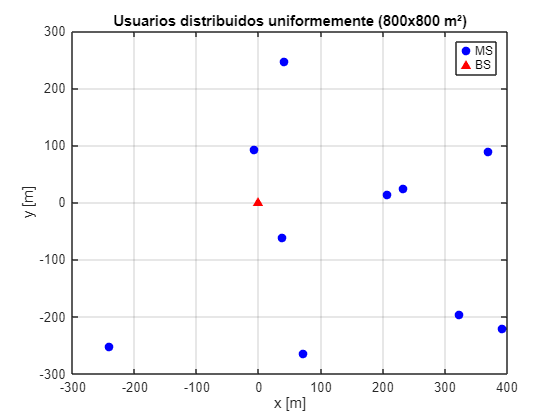

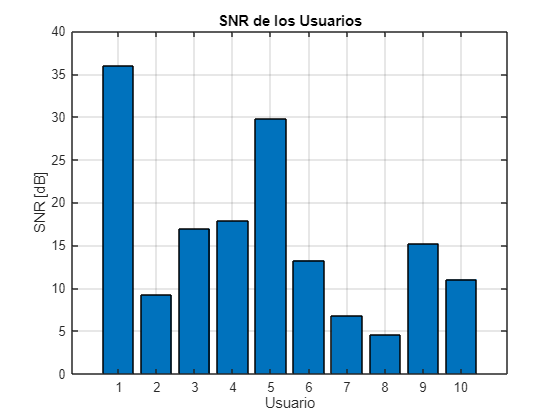

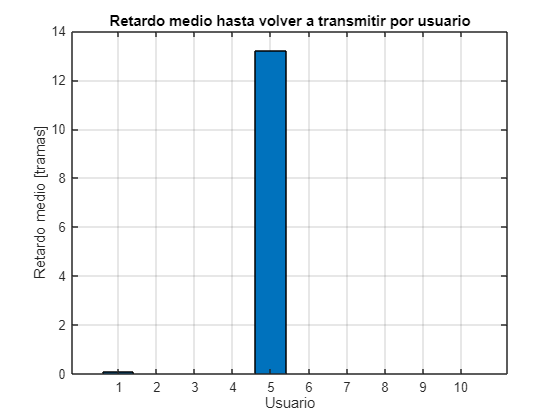

Usuario seleccionado final: 1      Vector de retardo final: 0  300  300  300   16  300  300  300  300  300


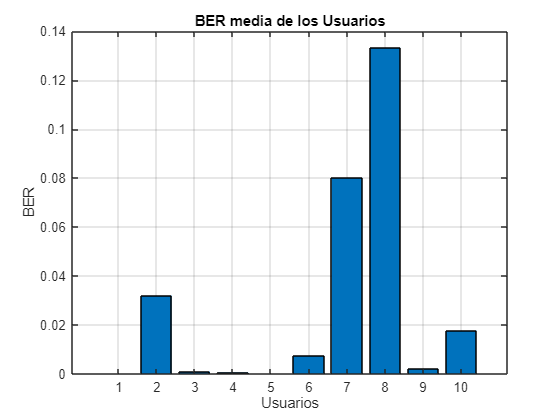

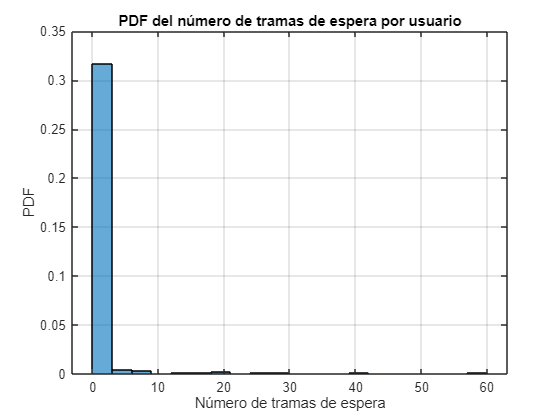

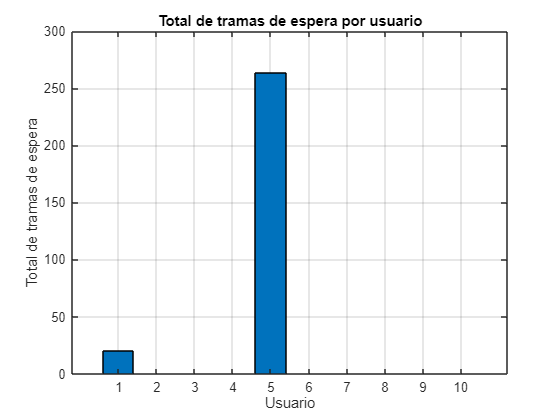

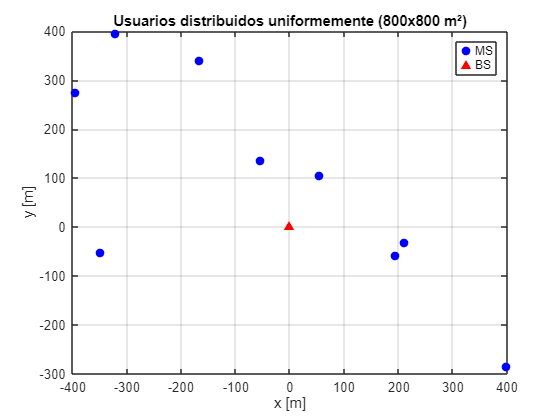

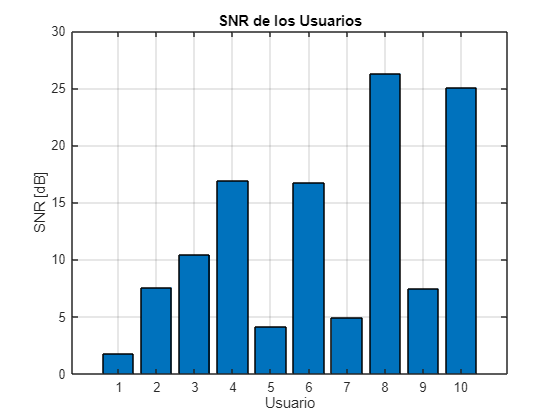

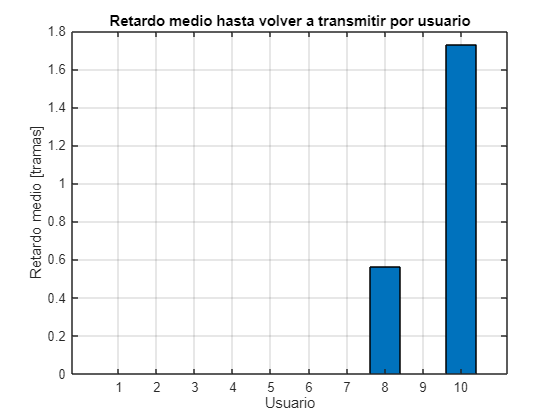

Usuario seleccionado final: 8      Vector de retardo final: 300  300  300  300  300  300  300    0  300    5


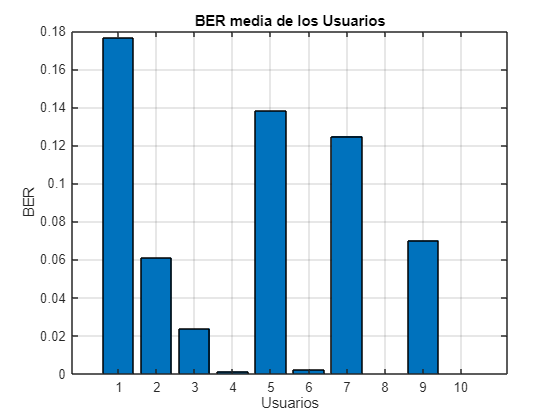

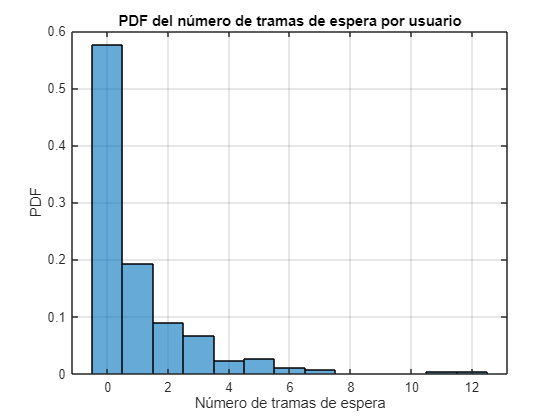

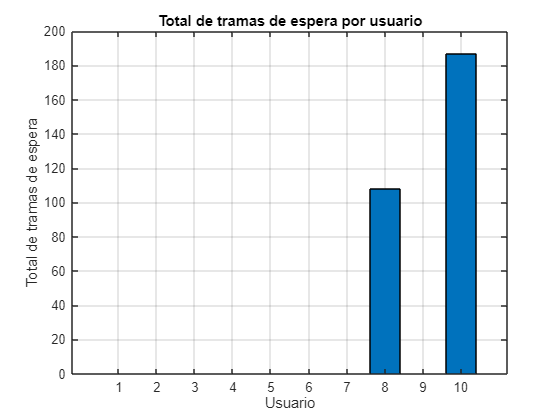

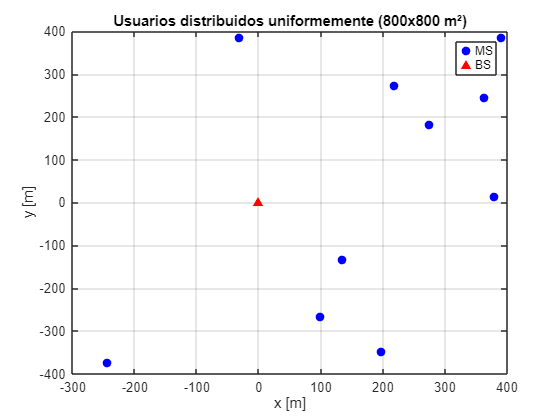

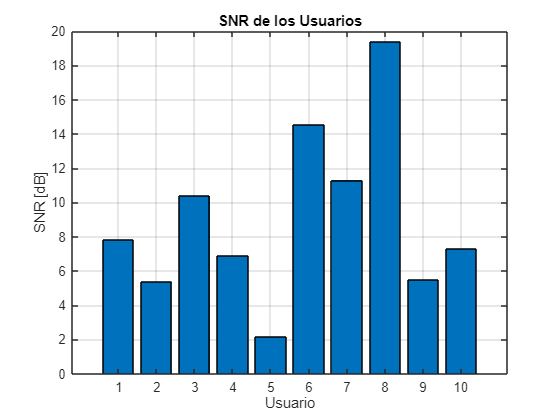

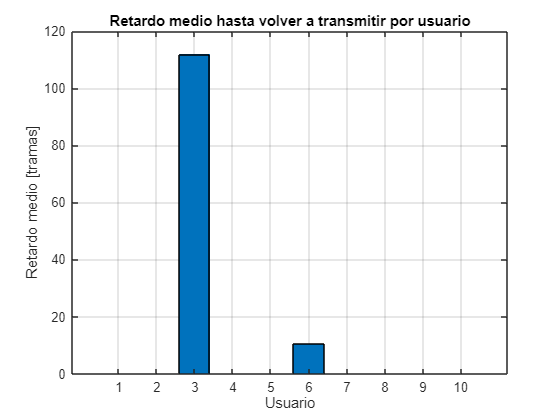

Usuario seleccionado final: 8      Vector de retardo final: 300  300  187  300  300   26  300    0  300  300


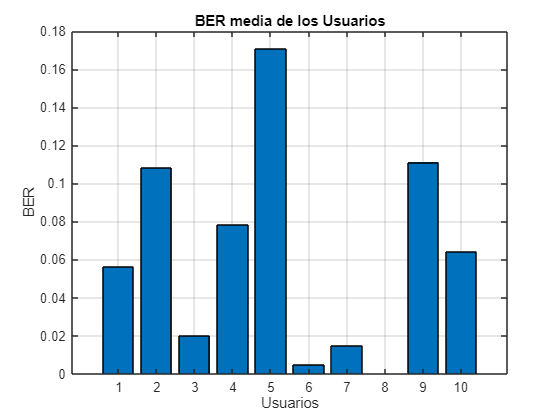

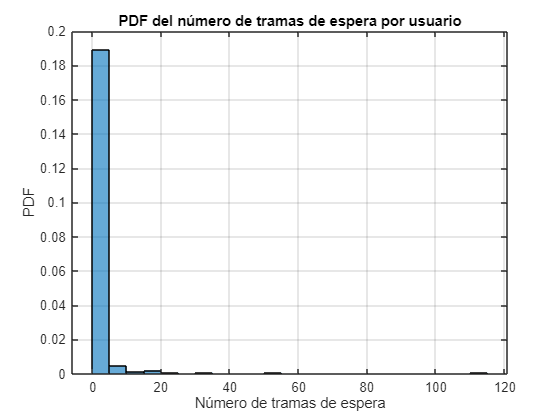

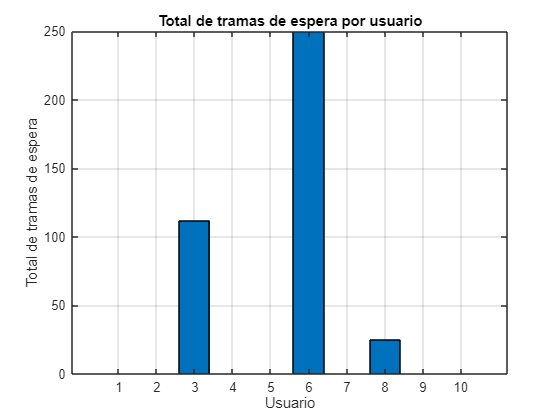

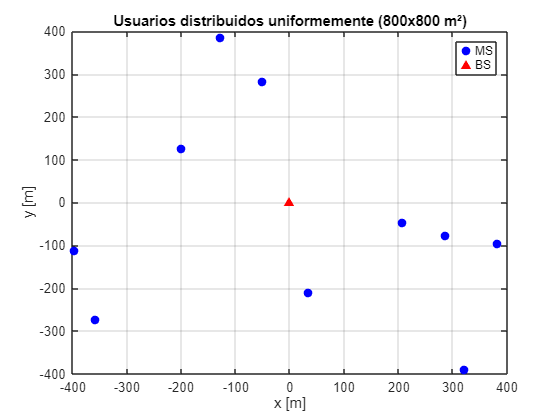

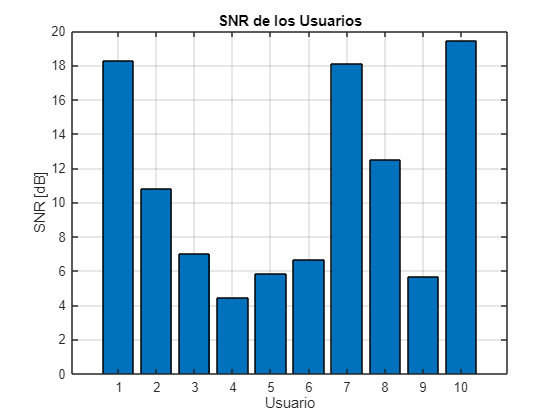

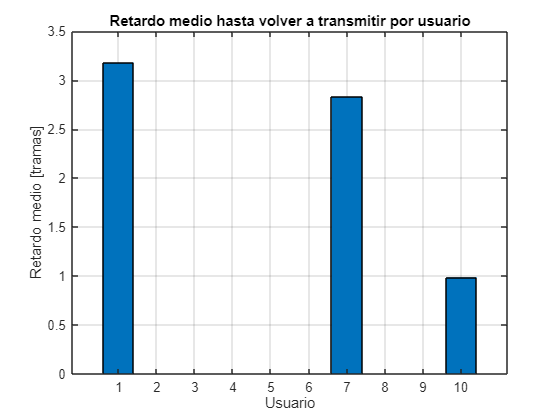

Usuario seleccionado final: 10      Vector de retardo final: 3  300  300  300  300  300    1  300  300    0


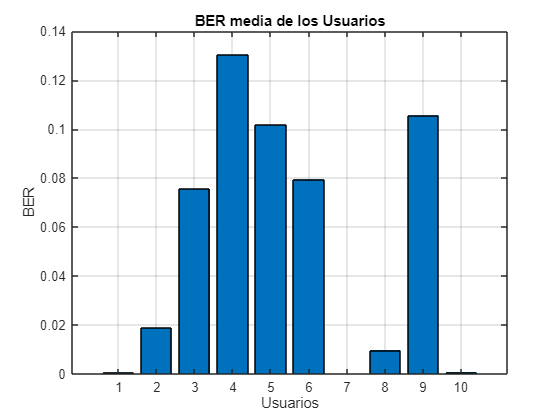

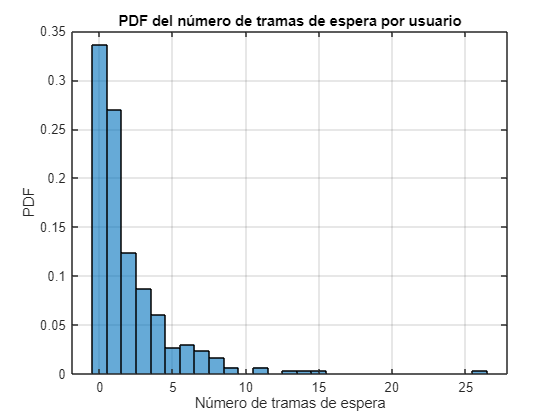

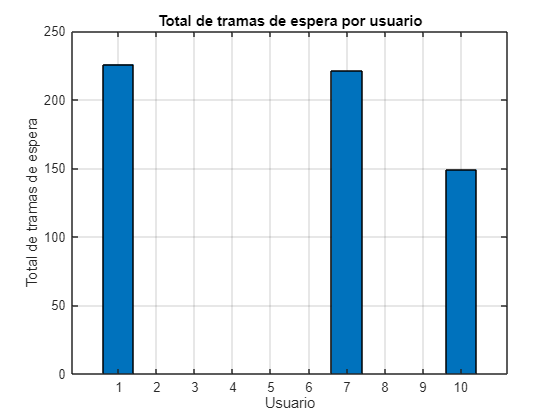

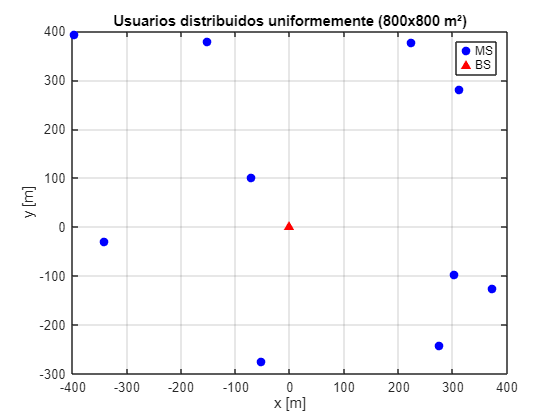

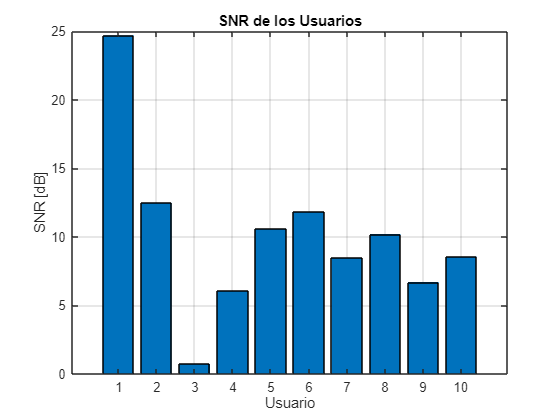

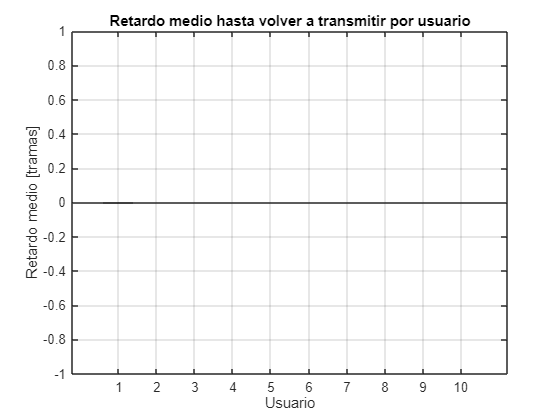

Usuario seleccionado final: 1      Vector de retardo final: 0  300  300  300  300  300  300  300  300  300


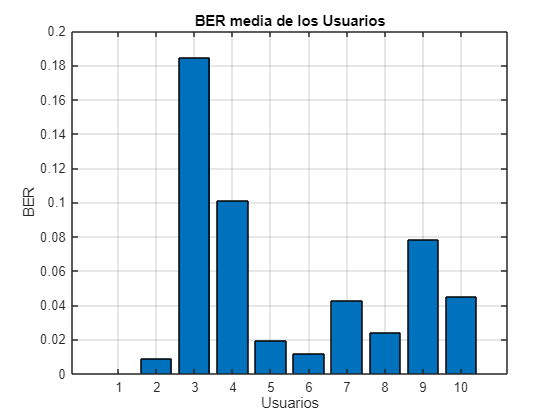

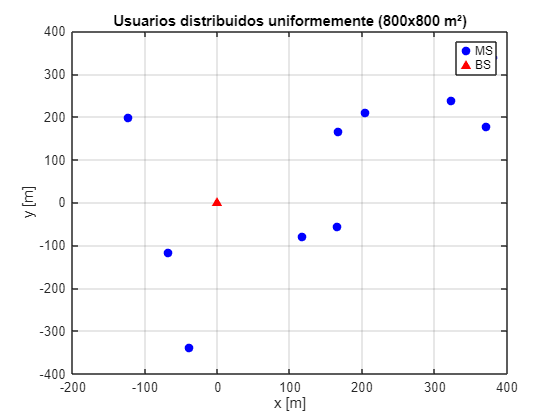

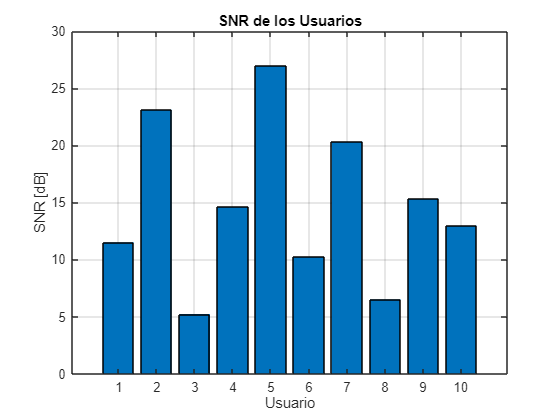

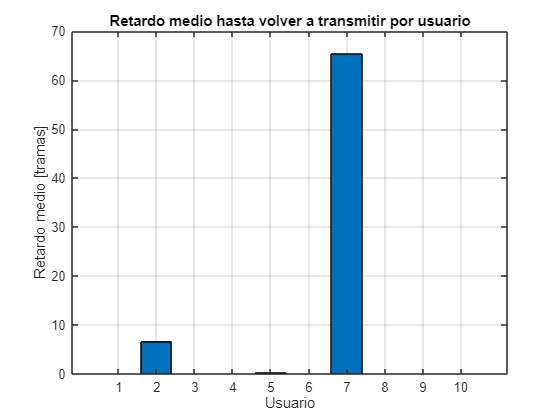

Usuario seleccionado final: 5      Vector de retardo final: 300    9  300  300    0  300   34  300  300  300


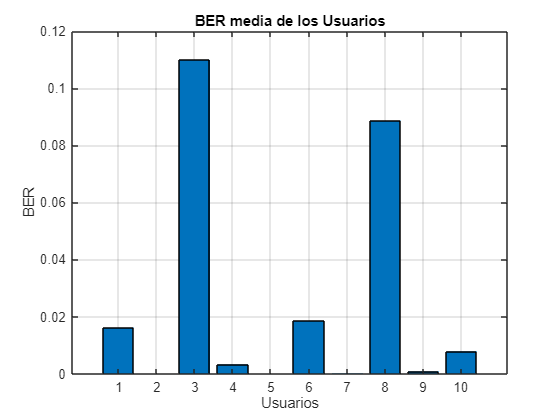

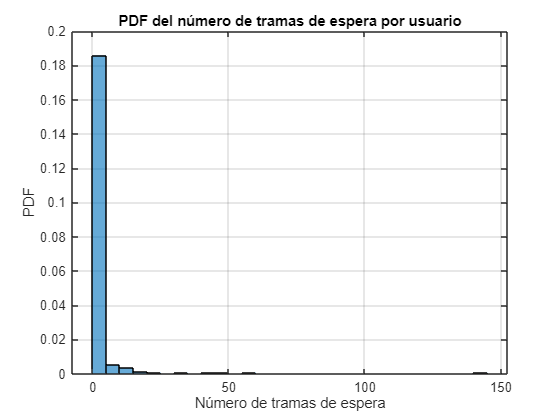

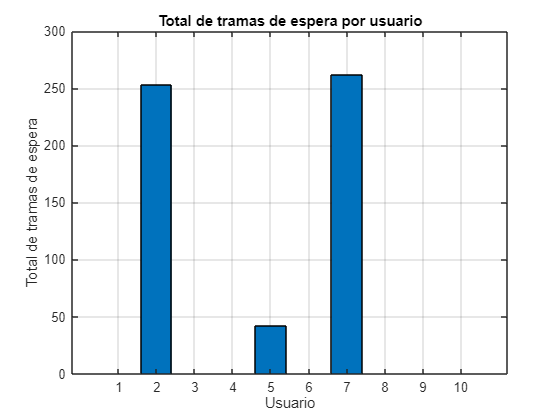

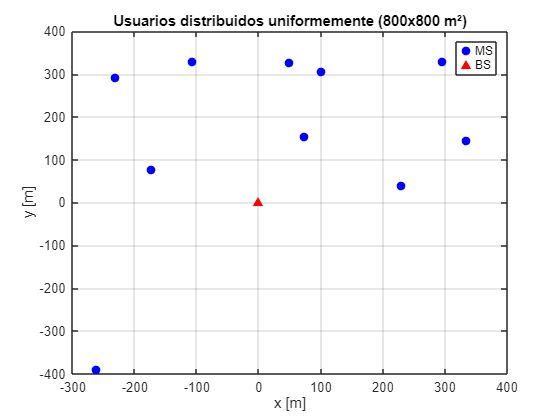

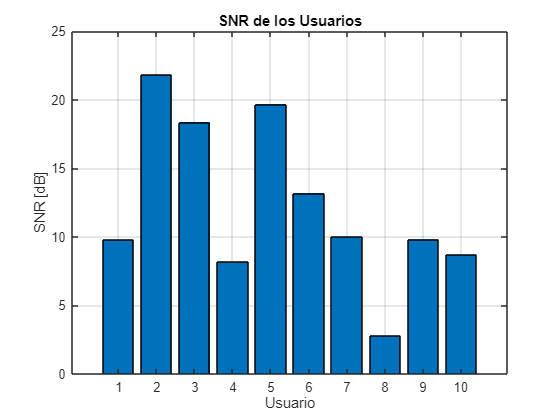

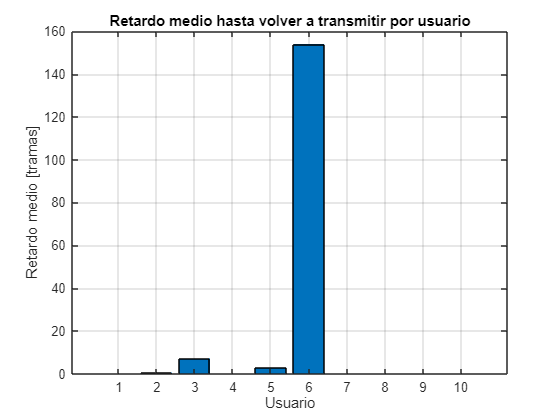

Usuario seleccionado final: 2      Vector de retardo final: 300    0   13  300    7  145  300  300  300  300


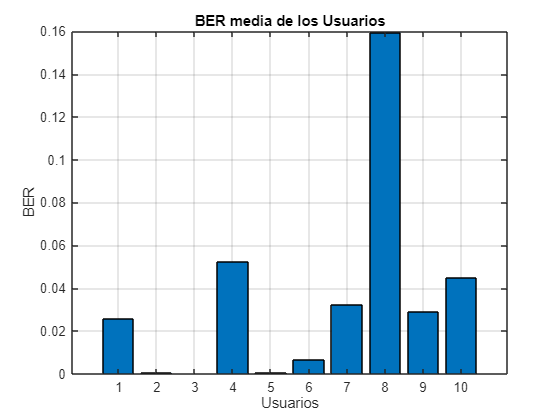

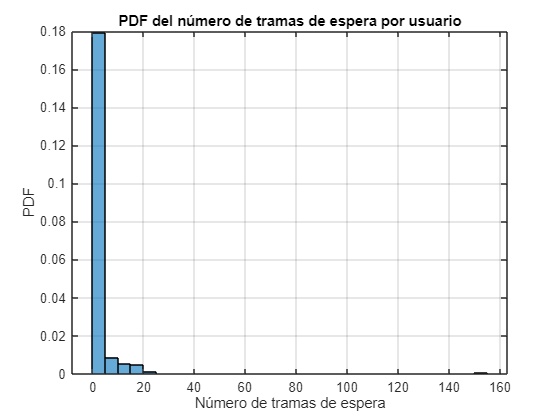

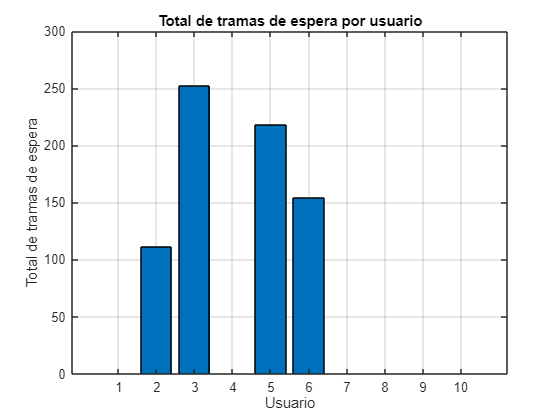

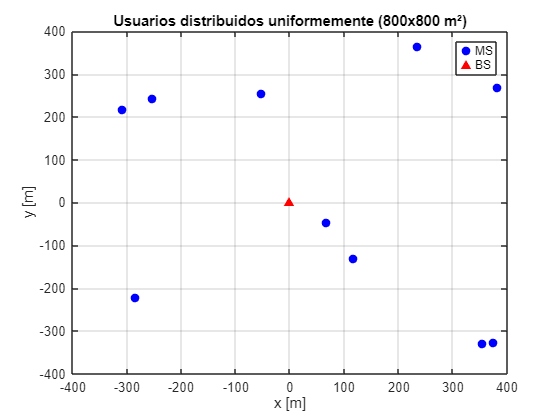

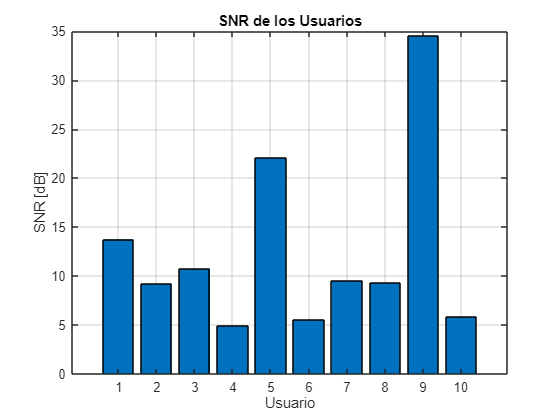

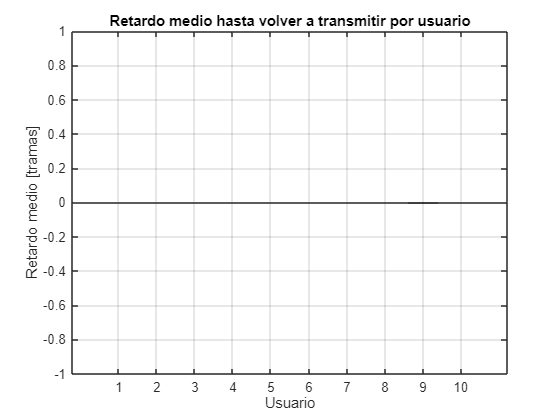

Usuario seleccionado final: 9      Vector de retardo final: 300  300  300  300  300  300  300  300    0  300


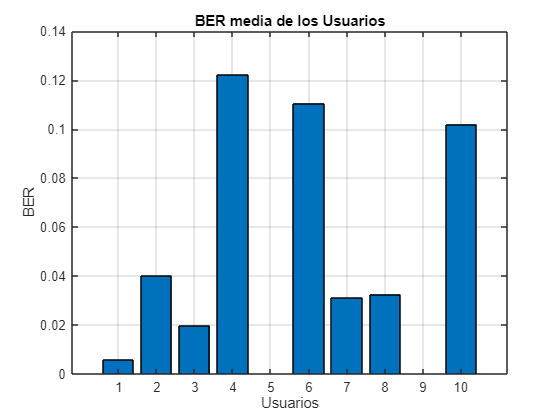

%Inicializo las variables nuevamente para realizar las futuras simulaciones
retardos_all = cell(K, 1);   
BER_all = cell(K, 1);        
tasa_all = cell(K, 1);       
delay_vector = zeros(1, K);  
selected_users = [];
user_tx_count = zeros(1, K);

% Montecarlo con Frecuencia Doppler = 120 y algoritmo de maxsnr
for i = 1:nbrofSetups
    % --------------------------------------
    % Opción 1: Área rectangular 800x800 m
    % --------------------------------------
    lado_x = 800;
    lado_y = 800;
    option1 = 1;
    Pos_MS1 = Calc_Pos_MS(option1, K, 0, 0, lado_x, lado_y);
    
    % -----------------------
    % Visualización
    % -----------------------
    figure;
    plot(real(Pos_MS1), imag(Pos_MS1), 'bo', 'MarkerFaceColor', 'b');
    hold on;
    plot(real(Pos_BS), imag(Pos_BS), 'r^', 'MarkerFaceColor', 'r');
    title('Usuarios distribuidos uniformemente (800x800 m²)');
    xlabel('x [m]'); ylabel('y [m]');
    grid on; legend('MS','BS');
    
    % ---------------------------------------------
    % Cálculo inicial de la SNR de cada usuario
    % ---------------------------------------------
    
    SNRs = zeros(K, 1); % Vector para almacenar la SNR de cada usuario
    
    for k = 1:K
        dist = abs(Pos_BS - Pos_MS1(k)); % Distancia entre BS y usuario k
        SNRs(k) = calcular_SNRs(Pos_BS, Pos_MS1(k), Ptx, B, f, sigma_sh, N0); % Cálculo de SNR
    end

    % ---------------------------------------------
    % Visualización de las SNRs de los usuarios
    % ---------------------------------------------
    figure;
    bar(SNRs); % Representación gráfica en barras
    title('SNR de los Usuarios');
    xlabel('Usuario');
    ylabel('SNR [dB]');
    grid on;

    % ---------------------------------------------
    % Parámetros de simulación y Scheduler
    % ---------------------------------------------
    
    SNR_avg = mean(SNRs); % SNR media de todos los usuarios
    delay_vector = zeros(1, K); % Inicializa el vector de retardos
    num_tramas = num_muestras / 32; % Cada trama representa 32 símbolos
    
    % Casos con algoritmo de utilidad para las distintas frecuencias Doppler
    algoritmo = 'maxsnr'; % Algoritmo de planificación

    % --- Simulación con frecuencia de Doppler = 120 Hz ---
    SNR_instantanea = Apply_Rayleigh_Channel(SNRs, fd_values(3), num_muestras, ts);
    SNR_instantanea = SNR_instantanea(:, 1:32:end); % Tomar columnas cada 32 muestras
    
    [selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = ...
        Scheduler(SNR_instantanea, delay_vector, SNR_avg, algoritmo, num_tramas);
    
    plotMeanDelay(retardos);
    disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

    BER_k = Calculate_BER(SNR_instantanea, M);  % Cálculo de BER por usuario

    % Visualización de la BER media de los usuarios
    figure;
    bar(BER_k); % Representación gráfica en barras
    title('BER media de los Usuarios');
    xlabel('Usuarios');
    ylabel('BER');
    grid on;

    % Generación de bits a transmitir
    num_bits = log2(M) * num_muestras; % 4 bits por símbolo
    btx = randi([0 1], K, num_bits);
    
    % Transmisión 16QAM
    [brx, y] = Transmit_16QAM(btx, selected_users, SNR_instantanea, M);

    % Cálculo de la tasa transmitida a cada usuario
    tasa_k = user_tx_count * 32 / (num_muestras / B);  % tasa en Mb/s (aprox)

    % Acumulación por usuario (corregida)
    for k = 1:K
        retardos_all{k} = [retardos_all{k}, retardos{k}];   % concatenar retardos
        BER_all{k} = [BER_all{k}, BER_k(k)];                % concatenar BER media
        tasa_all{k} = [tasa_all{k}, tasa_k(k)];             % concatenar tasa media
    end

    % --- PDF del número total de tramas de espera ---
    all_delays = cell2mat(retardos);  % Unifica todas las celdas

    total_tramas_espera = sum(all_delays);  % Tramas totales de espera
    
    figure;
    histogram(all_delays, 'Normalization', 'pdf');
    xlabel('Número de tramas de espera');
    ylabel('PDF');
    title('PDF del número de tramas de espera por usuario');
    grid on;

    total_delays_per_user = cellfun(@sum, retardos);
    
    figure;
    bar(1:K, total_delays_per_user);
    xlabel('Usuario');
    ylabel('Total de tramas de espera');
    title('Total de tramas de espera por usuario');
    grid on;
end

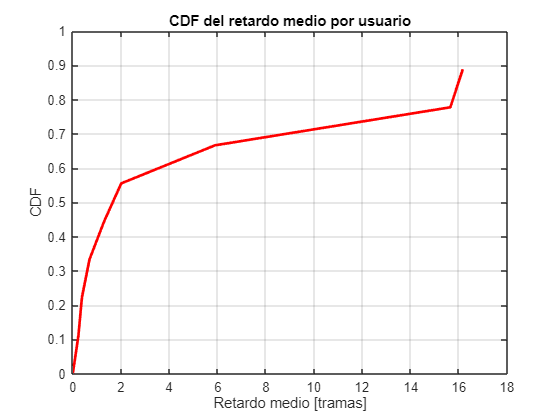


% --- CDF del retardo medio por usuario ---
% Cada celda de retardos_all{k} contiene los retardos acumulados del usuario k
retardo_medio_por_usuario = cellfun(@mean, retardos_all);     
retardo_ordenado = sort(retardo_medio_por_usuario);
cdf_retardo = linspace(0, 1, length(retardo_ordenado));
figure;
plot(retardo_ordenado, cdf_retardo, 'r-', 'LineWidth', 2);
xlabel('Retardo medio [tramas]');
ylabel('CDF');
title('CDF del retardo medio por usuario');
grid on;
ylim([0 1]);

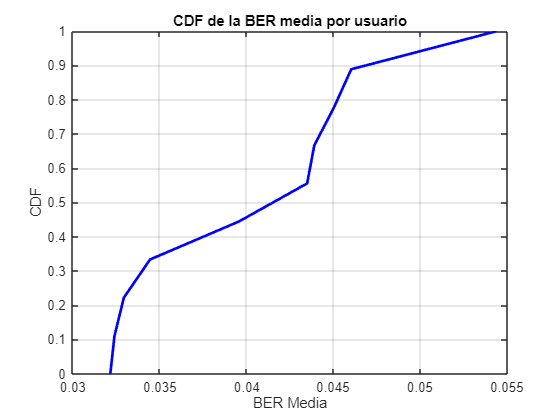


% --- CDF de la BER media por usuario ---
% Cada celda de BER_all{k} contiene las BERs acumuladas del usuario k
ber_media_por_usuario = cellfun(@mean, BER_all);              
ber_ordenado = sort(ber_media_por_usuario);
cdf_ber = linspace(0, 1, length(ber_ordenado));
figure;
plot(ber_ordenado, cdf_ber, 'b-', 'LineWidth', 2);
xlabel('BER Media');
ylabel('CDF');
title('CDF de la BER media por usuario');
grid on;
ylim([0 1]);

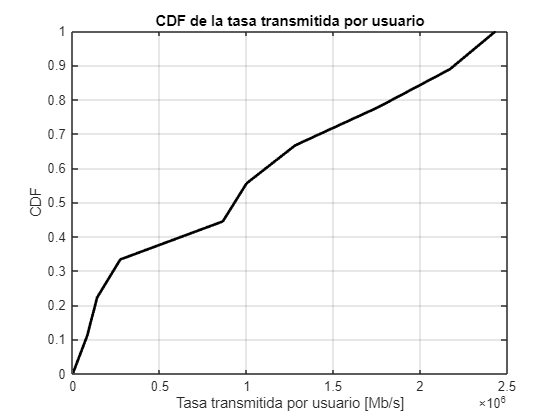


% --- CDF de la tasa transmitida por usuario ---
% Cada celda de tasa_all{k} contiene las tasas acumuladas del usuario k
tasa_media_por_usuario = cellfun(@mean, tasa_all);           
tasa_ordenada = sort(tasa_media_por_usuario);
cdf_tasa = linspace(0, 1, length(tasa_ordenada));
figure;
plot(tasa_ordenada, cdf_tasa, 'k-', 'LineWidth', 2);
xlabel('Tasa transmitida por usuario [Mb/s]');
ylabel('CDF');
title('CDF de la tasa transmitida por usuario');
grid on;
ylim([0 1]);